# Load Trained Model

Load the pretrained CNN and labels.

load('./model/trainedNetBalanced.mat', 'trainedNet')
labels = trainedNet.Layers(end).Classes

labels = 16×1 categorical array
     brush teeth 
     chop 
     dish 
     door 
     drop 
     eat 
     fart 
     fry boil 
     gargle 
     pee 
     speech 
     toilet 
     tv 
     unknown 
     vacuum 
     water 


labels = ["brush teeth"; "chop"; "dish"; "door"; "drop"; "eat"; "fart"; "fry boil";
    "gargle"; "pee"; "speech"; "toilet"; "tv"; "unknown"; "vacuum"; "water"]

labels = 16×1 string array
    "brush teeth"
    "chop"
    "dish"
    "door"
    "drop"
    "eat"
    "fart"
    "fry boil"
    "gargle"
    "pee"
    "speech"
    "toilet"
    "tv"
    "unknown"
    "vacuum"
    "water"


NumLabels = numel(labels)

NumLabels = 16

# Define Parameters for Streaming Audio

Use the same parameters for the feature extraction pipeline and classification as trained network.

fs = 16000;
classificationRate = 10;
samplesPerCapture = fs/classificationRate;

segmentDuration = 1;
segmentSamples = round(segmentDuration*fs);

frameDuration = 0.025;
frameSamples = round(frameDuration*fs);

hopDuration = 0.010;
hopSamples = round(hopDuration*fs);

numSpectrumPerSpectrogram = floor((segmentSamples-frameSamples)/hopSamples) + 1;

# Define Feature Parameters for Streaming Audio

Create an [`audioFeatureExtractor`](https://kr.mathworks.com/help/audio/ref/audiofeatureextractor.html) object to extract Melspectrograms without window normalization. Calculate the number of elements in each spectrogram.

afe = audioFeatureExtractor( ...
    'SampleRate',fs, ...
    'FFTLength',512, ...
    'Window',hann(frameSamples,'periodic'), ...
    'OverlapLength',frameSamples - hopSamples, ...
    'melSpectrum',true);

numBands = 128;
setExtractorParams(afe, 'melSpectrum','NumBands',numBands,'WindowNormalization',false);

numElementsPerSpectrogram = numSpectrumPerSpectrogram*numBands;

# Create Streaming Audio Reader

Create an [`audioDeviceReader`](https://kr.mathworks.com/help/audio/ref/audiodevicereader-system-object.html) object to read audio from your device. Create a [`dsp.AsyncBuffer`](https://kr.mathworks.com/help/dsp/ref/dsp.asyncbuffer-system-object.html) object to buffer the audio into chunks.

audioBuffer = dsp.AsyncBuffer(fs);

# Create Viewer for Streaming Audio

Create a [`dsp.MatrixViewer`](https://kr.mathworks.com/help/dsp/ref/dsp.matrixviewer-system-object.html) object and a [`timescope`](https://kr.mathworks.com/help/dsp/ref/timescope.html) object to display the results.

matrixViewer = dsp.MatrixViewer("ColorBarLabel","Power per band (dB/Band)",...
    "XLabel","Frames",...
    "YLabel","Mel Bands", ...
    "Position",[400 100 600 250], ...
    "ColorLimits",[-4 2.6445], ...
    "AxisOrigin","Lower left corner", ...
    "Name","Sound Event Detection using Deep Learning");

timeScope = timescope("SampleRate",fs, ...
    "YLimits",[-1 1], ...
    "Position",[400 380 600 250], ...
    "Name","Sound Event Detection Using Deep Learning", ...
    "TimeSpanSource","Property", ...
    "TimeSpan",1, ...
    "BufferLength",fs, ...
    "YLabel","Amplitude", ...
    "ShowGrid",true);

predictionViewer = dsp.MatrixViewer( "CustomYData", [1, NumLabels], ...
    "YOffset", 1, ...
    "ColorBarLabel", "Probability", ...
    "XLabel","Classification Window",...
    "YLabel", "Class",...
    "ColorLimits",[0 1], ...
    "AxisOrigin","Lower left corner", ...
    "ShowGrid", true, ...
    "Name","Sound Event Detection using Deep Learning");

# Show Streaming Audio

Show the time scope and matrix viewer. Detect commands as long as both the time scope and matrix viewer are open or until the time limit is reached. To stop the live detection before the time limit is reached, close the time scope window or matrix viewer window.

probBuffer = single(zeros([NumLabels,classificationRate]));
YBuffer = single(NumLabels * ones(1, classificationRate));

countThreshold = ceil(classificationRate*0.4);
probThreshold = single(0.5);

show(timeScope);
show(matrixViewer);
show(predictionViewer);

t=1;
afr = dsp.AudioFileReader('./audio/test_wash_brushteeth.wav', 'SamplesPerFrame', samplesPerCapture)

afr =   dsp.AudioFileReader with properties:

           Filename: './audio/test_wash_brushteeth.wav'
          PlayCount: 1
    SamplesPerFrame: 1600
     OutputDataType: 'double'
         SampleRate: 16000
          ReadRange: [1 Inf]


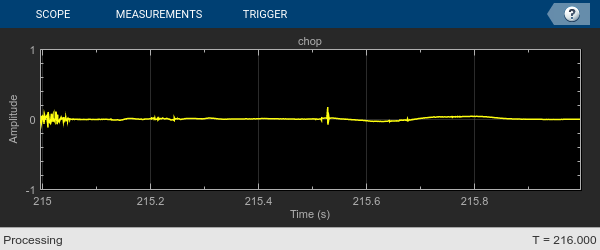

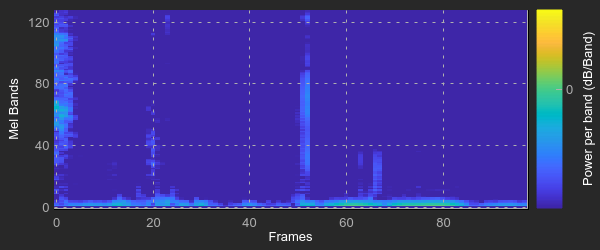

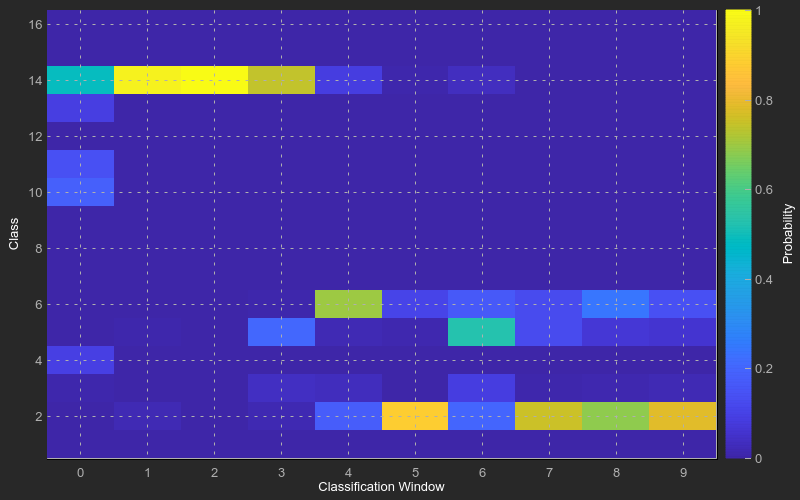


tic
while isVisible(timeScope) && isVisible(matrixViewer)
    % Capture audio
    [x,eof] = afr();
    
    if eof == 1
        break;
    end
    
    write(audioBuffer,x);
    y = read(audioBuffer,fs,fs-samplesPerCapture);   
    
    % Compute auditory features
    features = extract(afe,y);
    auditoryFeatures = log10(features + 1e-6);
    
    % Perform prediction
    probs = predict(trainedNet, auditoryFeatures);   
    [~, YPredicted] = max(probs);
    
    % Perform statistical post processing
    YBuffer = [YBuffer(2:end),YPredicted];
    probBuffer = [probBuffer(:,2:end),probs(:)];

    [YModeIdx, count] = mode(YBuffer);
    maxProb = max(probBuffer(YModeIdx,:));

    if single(count) < countThreshold || maxProb < probThreshold
        speechCommandIdx = -1;
    else
        speechCommandIdx = YModeIdx;
    end
    
    YHistory(t) = speechCommandIdx;
    t = t+1;
    
    % Update plots
    timeScope(x);
    matrixViewer(auditoryFeatures');
    predictionViewer(probBuffer);

    if (speechCommandIdx == -1)
        timeScope.Title = 'Unknown';
    else
        timeScope.Title = char(labels(speechCommandIdx));
    end

    drawnow limitrate 
end  

Hide the scopes.

hide(matrixViewer)
hide(timeScope)
hide(predictionViewer)

Save YHistory in history directory

save('./history/YHistory', 'YHistory')